This section assumes that you have access to the functions and basic kinematics of 4-CLARI. If you do not have access to the file "Data\nonslip4CLARIMobility.mat" from the root folder, then run the first section (might take some time to complete, maybe time it if needed) in "se2_fixedCLARImobility.mlx".

addpath 'Data'\ 'Utility Functions'\; 
load('Data\lvl2CSinfo.mat'); load('nonslipPlottingParamsMobility.mat');
load('Data\nonslip4CLARIMobility.mat');
set(groot, 'defaultAxesTickLabelInterpreter', 'latex'); 
set(groot, 'defaulttextinterpreter', 'latex');
set(groot, 'defaultLegendInterpreter', 'latex');

Below, we first show a rightward displacing gait of the 4-CLARI robot. In the maneuverability space shown below, the gait forms a phasor to the right which is indicative of the displacement generated by the right displacing gait. Note that in the first half of the gait cycle $\left[ 0, \pi^{-} \right]$ legs 1 (FR) and 3 (HL) stance and during the second half of the gait cycle $\left[ \pi, 2\pi^{-} \right]$ the other pair of legs are in stance. We do not directly edit the contact trajectory to obtain different displacements without rotation, but we do change the swing trajectory phase for each limb. (Also, there is probably an equivalent contact trajectory modulation, but we don't consider this.)

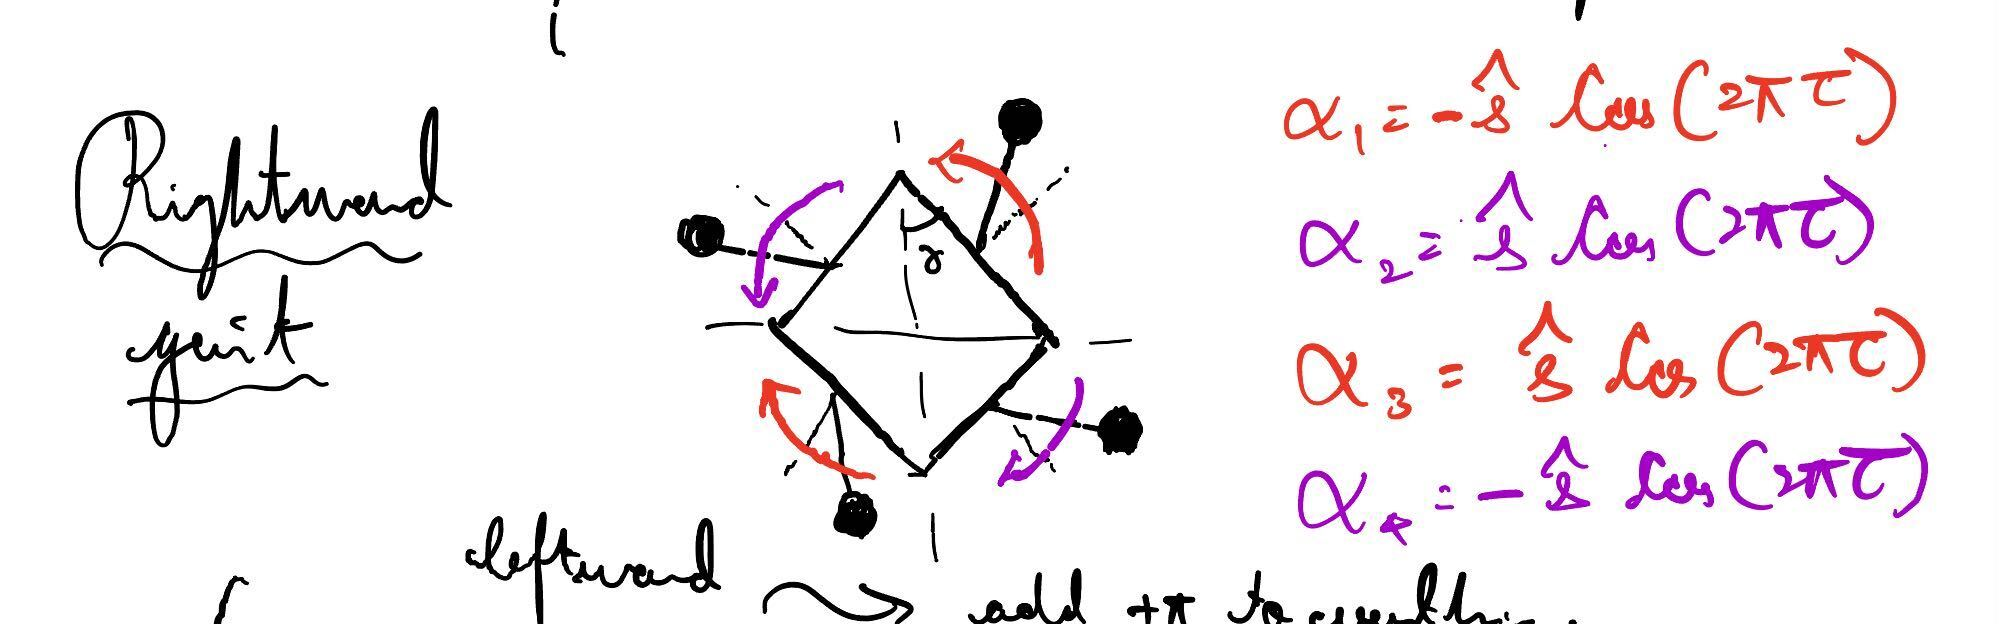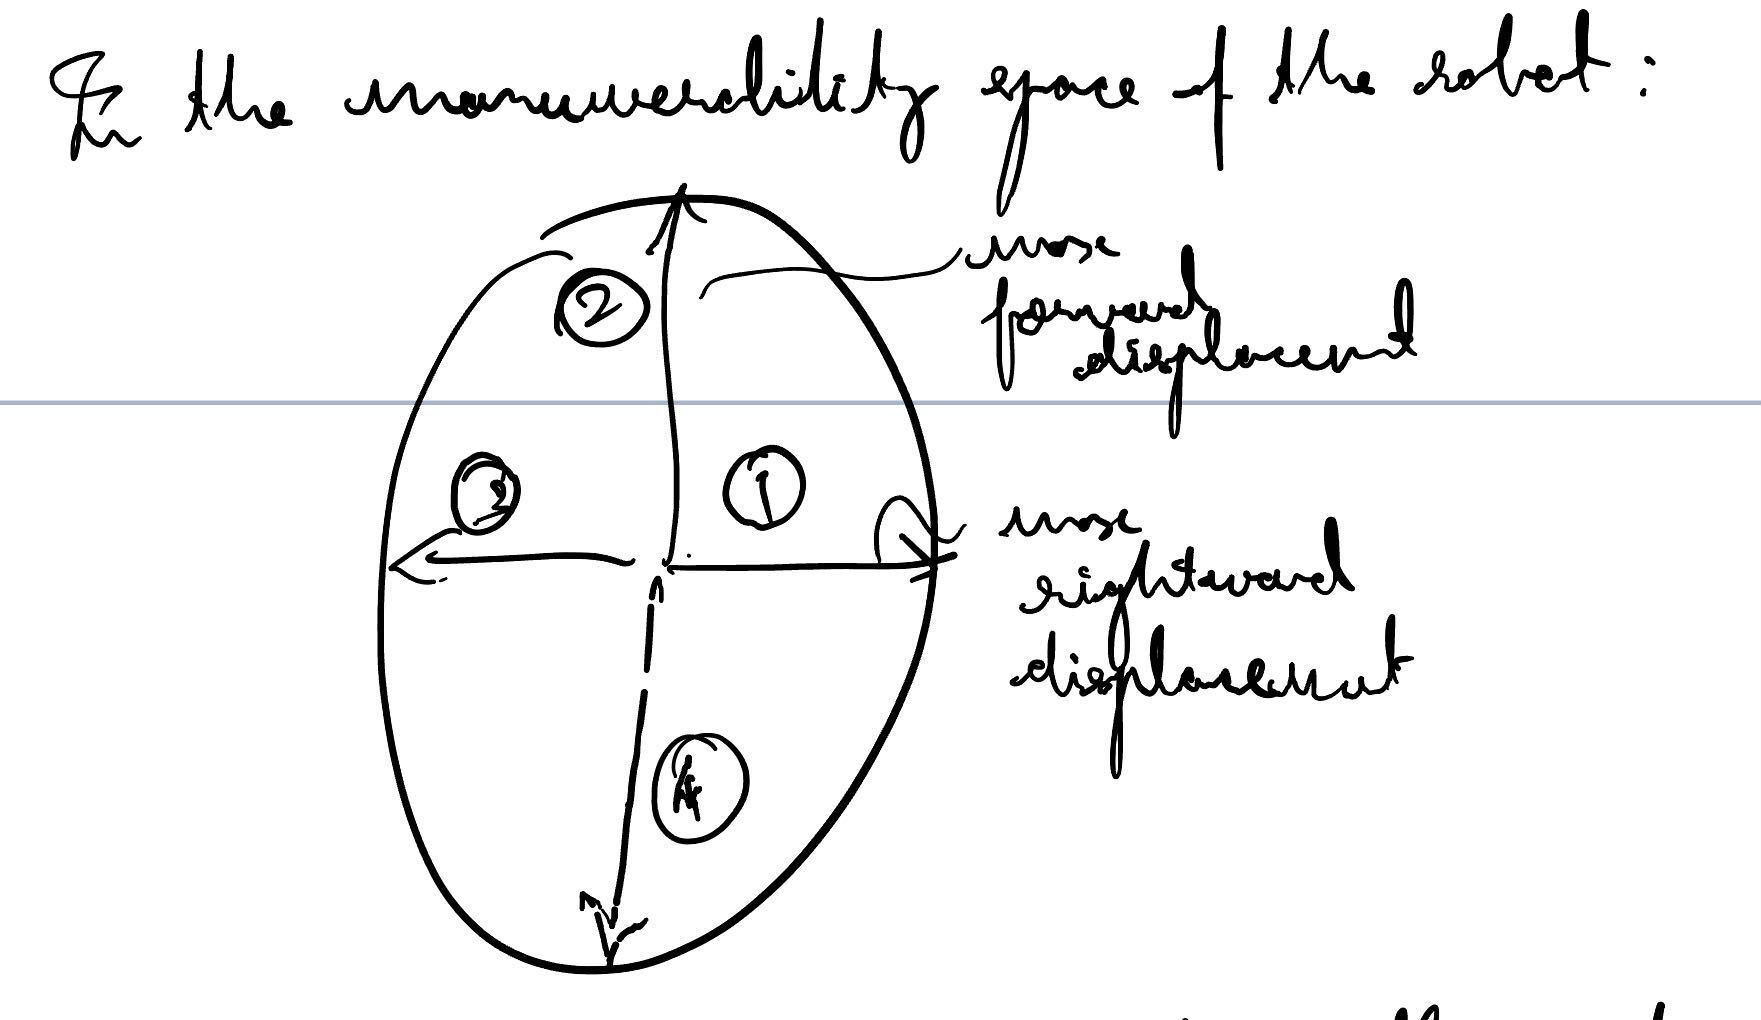

For additional clarification, a timeseries of a forward-displacing gait is provided below:

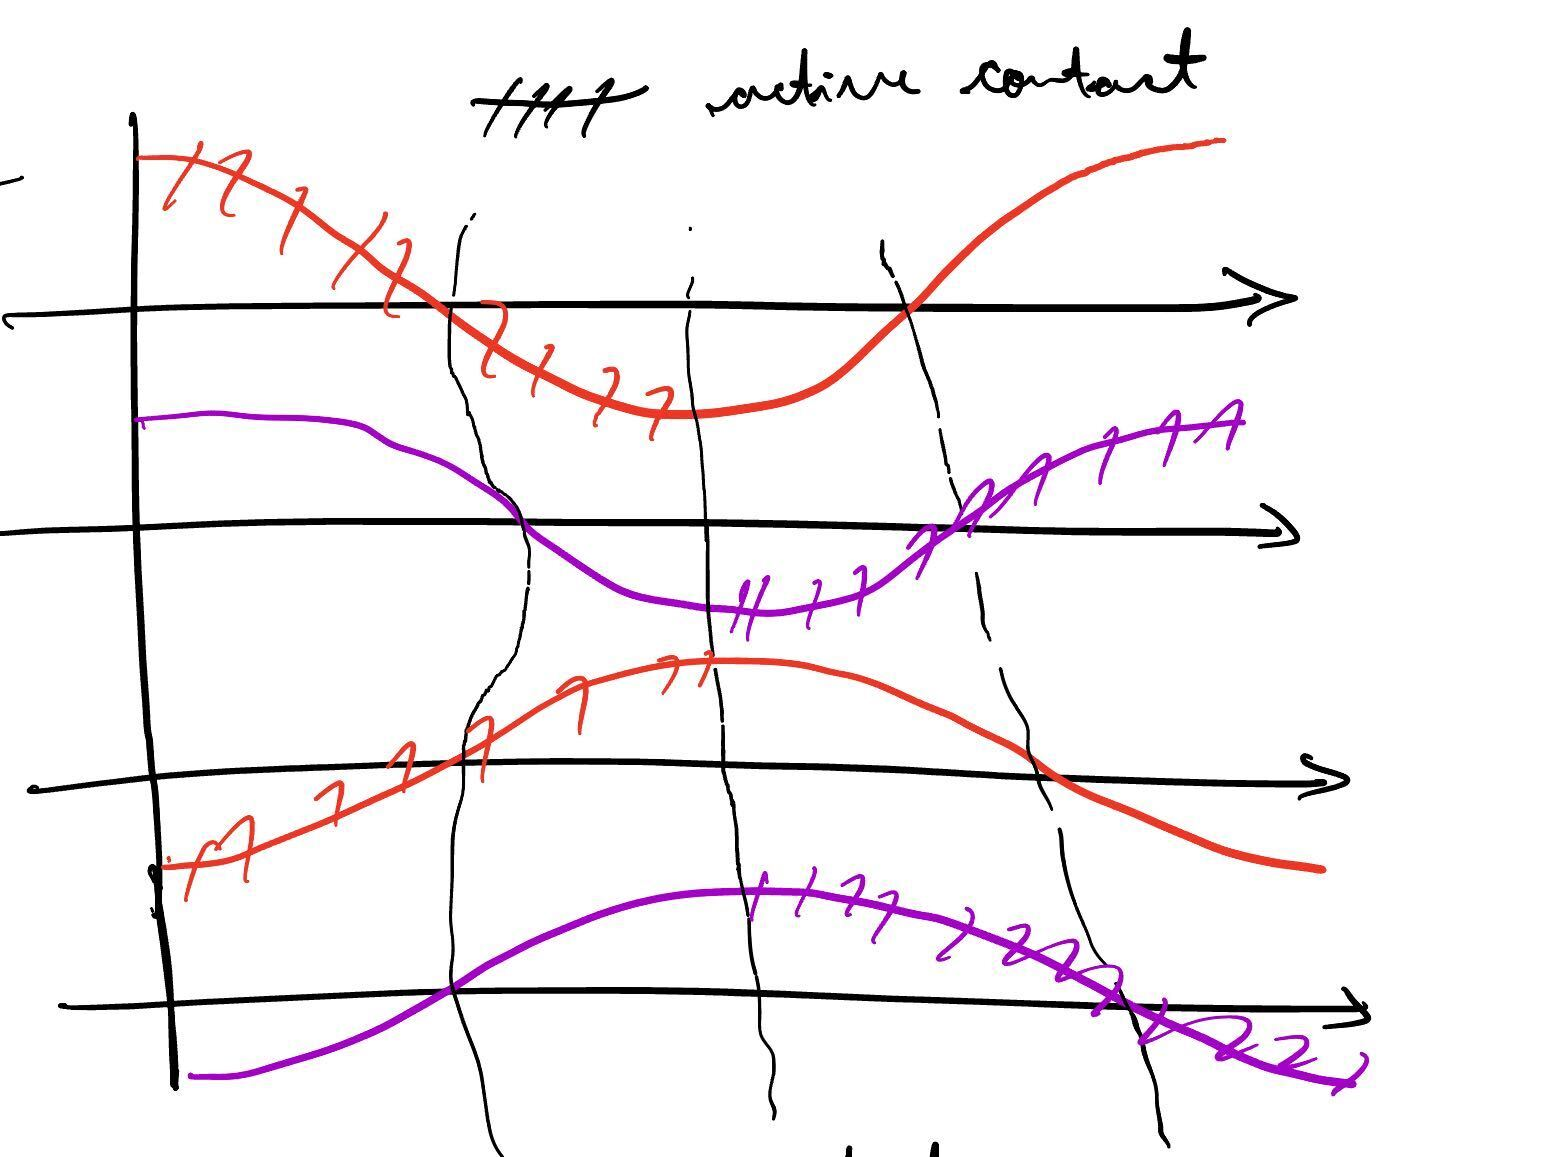

In the above timeseries, the hatched section of the trajectory corresponds to active contact state - this doesnt change in our implementation as mentioned above, only the swing phase changes.

Analytically we can work out the right phase to modulate the rightward-displacing gait into a forward displacing one, and then leftward, and finally backward-displacing gaits numbered 1)-4) in the above maneuverability space. However, for displacement along other phasors, the correct phase modulation is unclear. So we define the phases for each swing angle and linear interpolate between the gaits 1)-4) to obtain estimates of the system's ability to move in the other directions without accruing a net rotation -- or in other words, we sweep the maneuverability set:

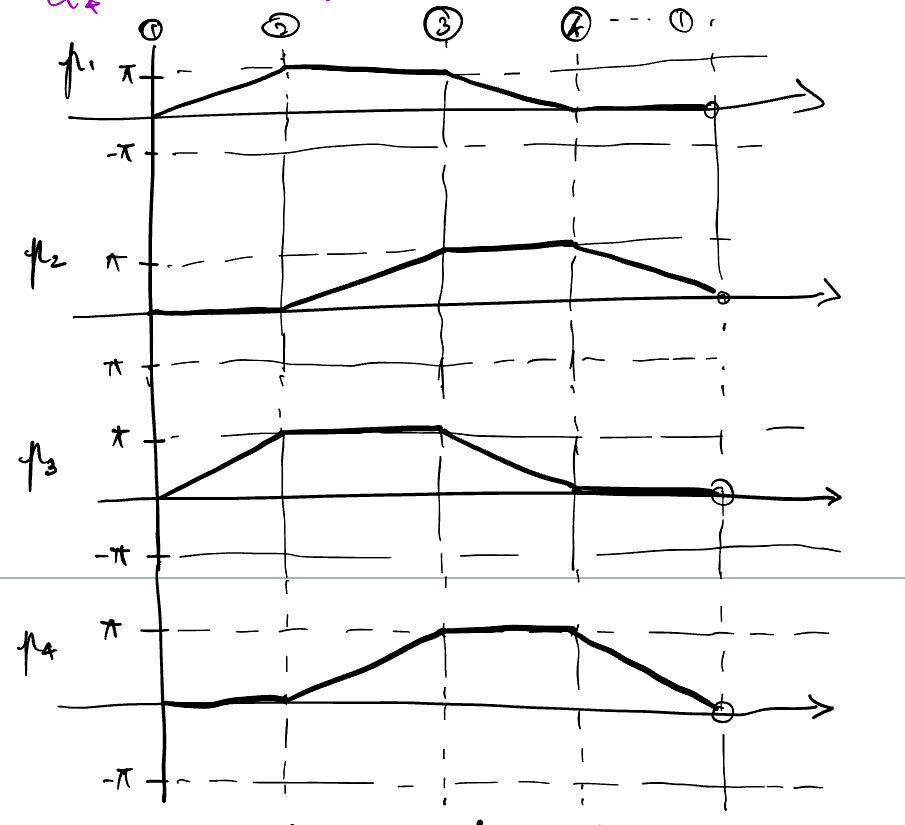

To construct this set, we need to define the rightward-displacing gait as the baseline gait and then add phase to it to sweep this set out. We setup some basic parameters below and definitions for the above gaits canbe found in "Utility Functions\simulateSineSwingGaits.m" function.

% some initial body morphing parameters setup
sIdx = cs_IdxFor2bGaits(strcmp(csString, 'Trot'), :); % obtain the current contact submanifolds for 
na = limbScalingParam(end); nl = 1; bodyLength = double(subs(bodyLength, l, nl)); % clari system construction params
nalpha_b = bodySprawlParam(end); % just set this to the omnidirectional (nominal) body morph angle
nalpha0 = limbAngleParam(end); % nominal limb swing angle
swingHat = pi/4; % choose the swing amplitude for all limbs

% extract the local connections for the trot gait setup
fA = {  fAfull_i{ sIdx(1) }; fAfull_i{ sIdx(2) }  };

% package the parameters for the simulation
params = [];
params.dnum = dnum;
params.na = na; params.nl = nl; 
params.nalpha_b = nalpha_b; 
params.sHat = swingHat;

Below we can compute the displacement generate by the rightward-displacing (+x body direction) trot gait as a sanity check. 

Uncomment to run.

% % SET the swing phase offset based on the current maneuverability phase
% mPhase = 0.00;
% % ... ... some options are given below .................
% % ... mPhase == 0.00: right-displacing trot gait
% % ... mPhase == 0.25: fwd  -displacing trot gait
% % ... mPhase == 0.50: left -displacing trot gait
% % ... mPhase == 0.75: bwd  -displacing trot gait
% % ... then it wraps back around to right-displacing gait
% 
% % simulate the system and normalize the body trajectory and displacement by
% % the body length of the system
% [tau, gb, zb] = simulateSineSwingGaits(fA, params, mPhase);
% % ... tau is the gait phase from 0 (ic) to 1 (fc)
% % ... gb is the (ntau x 3) body trajectory
% % ... zb is the (1 x 3) net body displacement
% gbN = gb; gbN(:, 1:2) = gbN(:, 1:2)/bodyLength;
% zbN = zb; zbN(1:2) = zbN(1:2)/bodyLength;
% disp(zbN)

The goal in this section is to sweep different maneuverability phases to generate the maneuverability map.

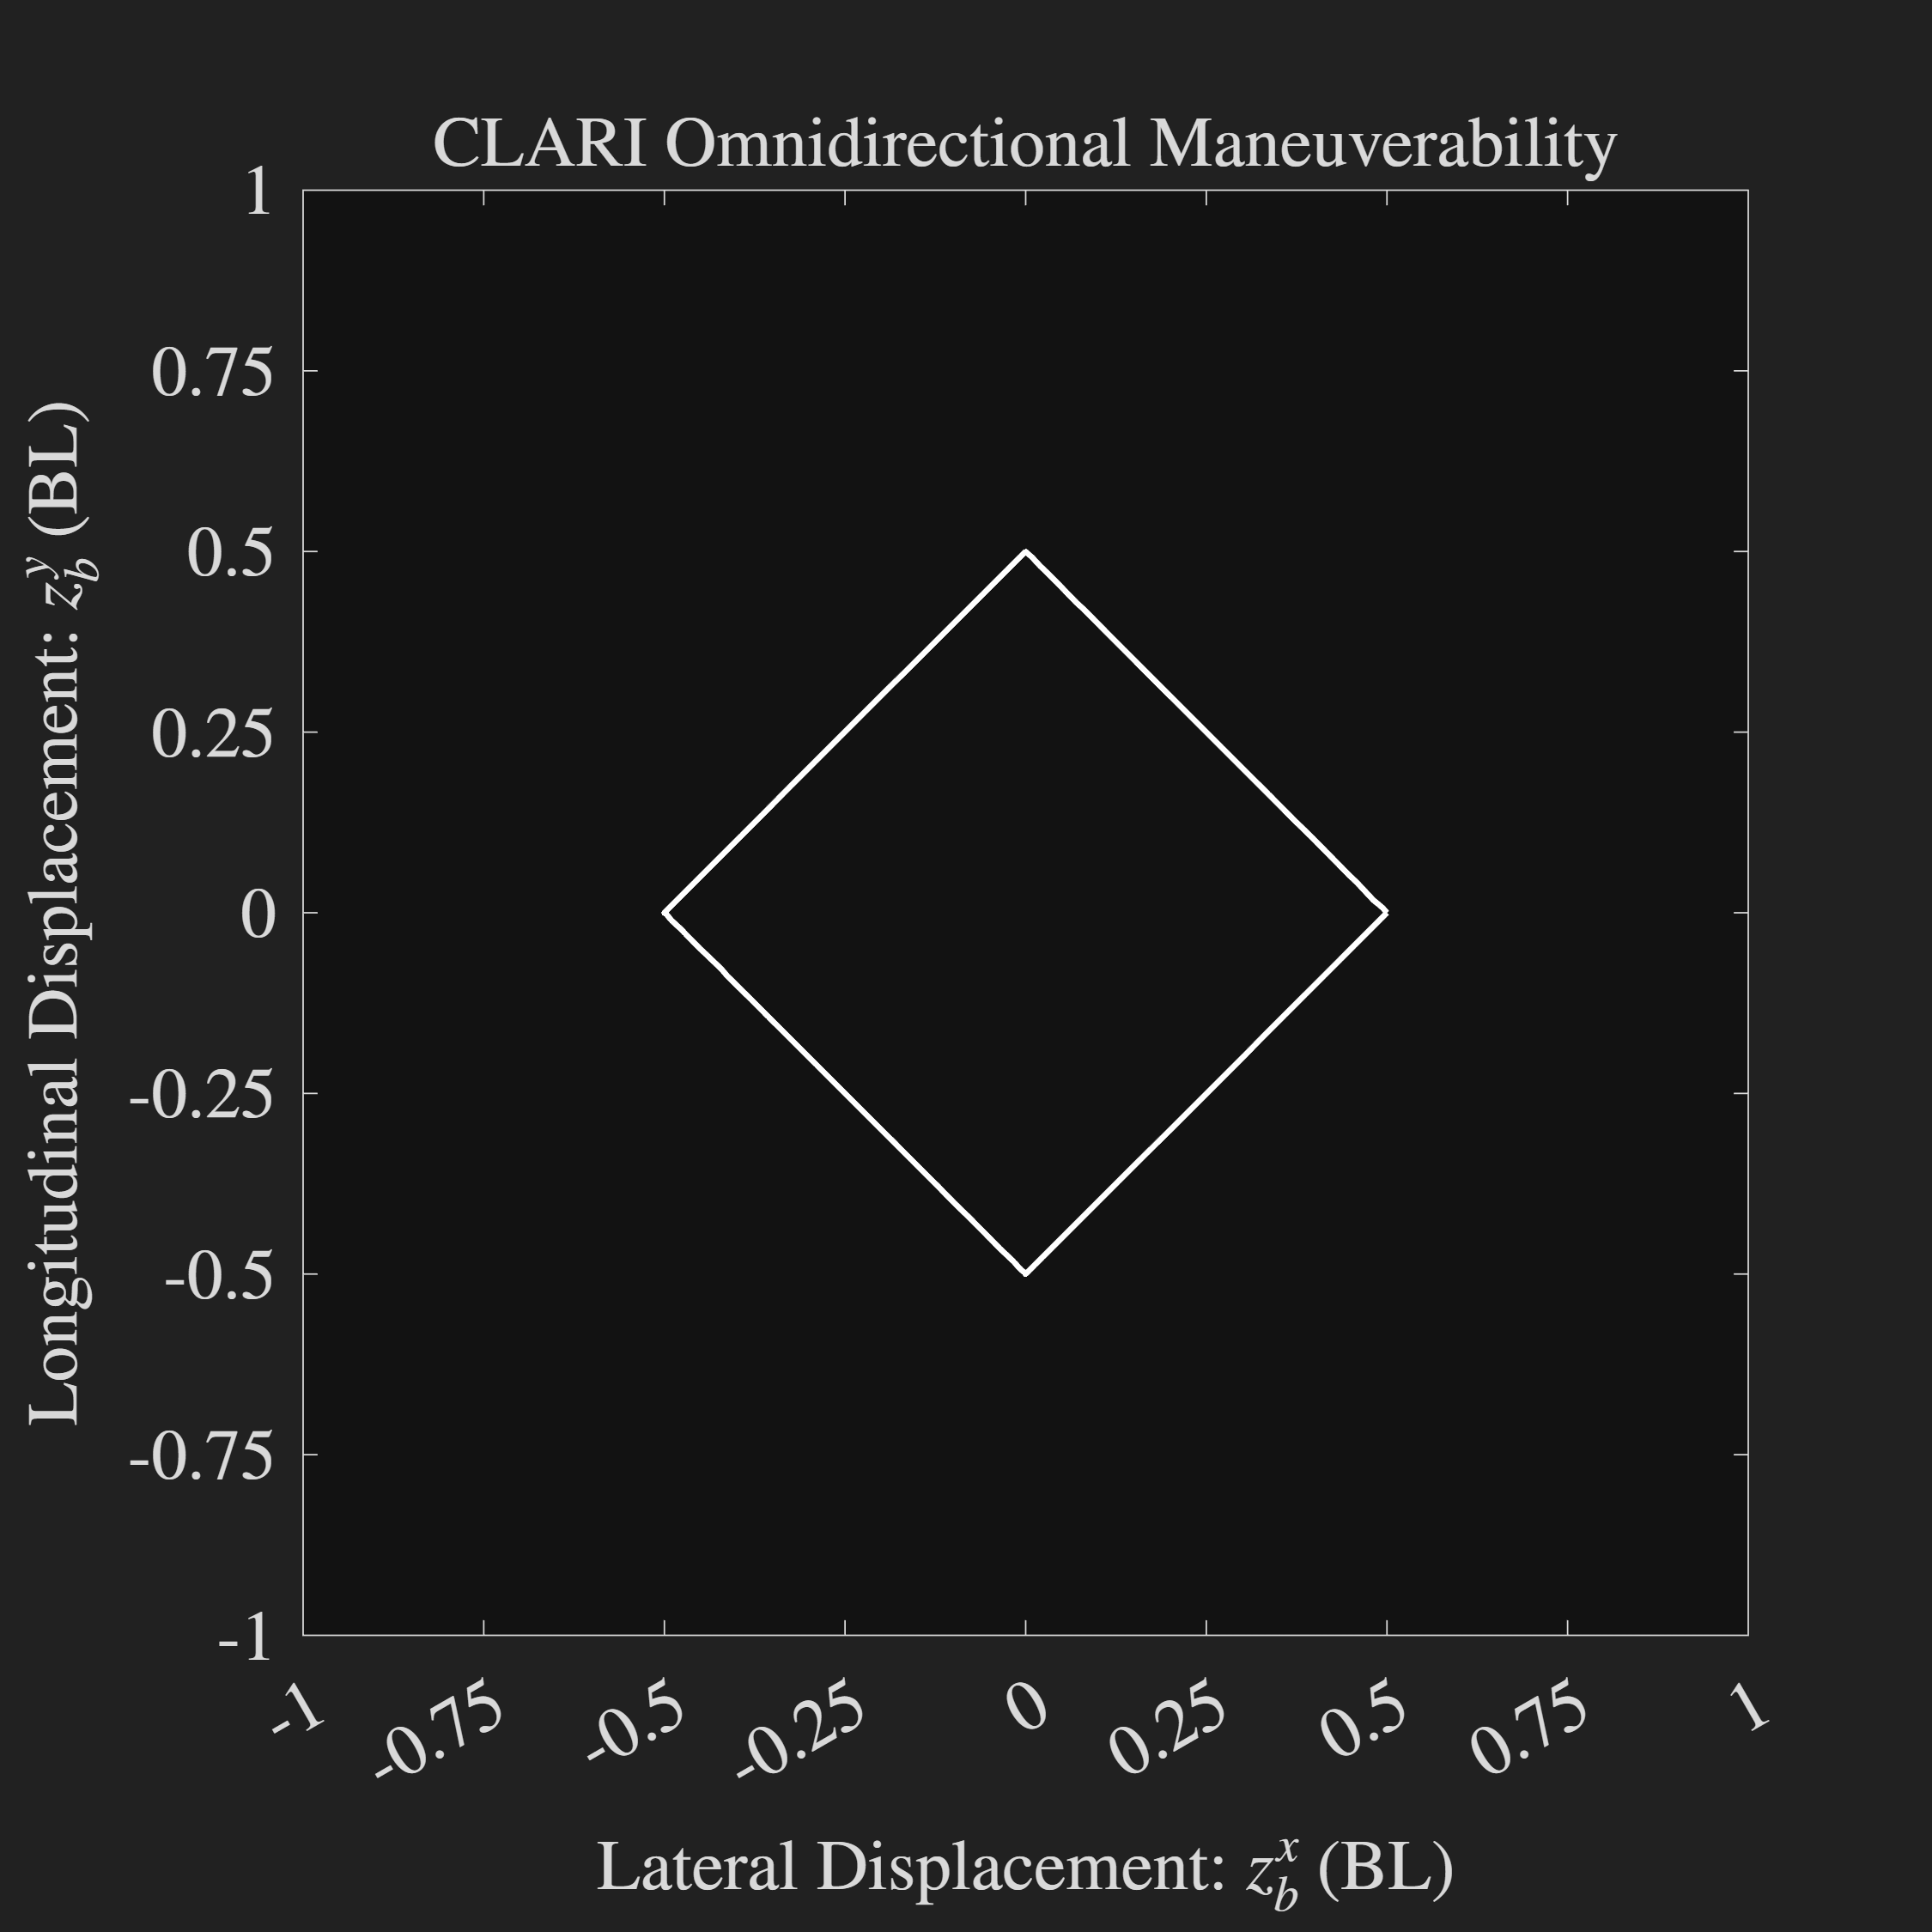

% array of maneuverability phases
% ... 1 is again 0 as the phase connects on itself
gNum = dnum;
mPhase = linspace(0, 1, gNum+1); 
mPhase = mPhase(1:end-1); % remove last point, same as zero

% iterate and compute the net displacement generated by each trot gait
zb = nan(gNum, 3);
for i = 1:gNum
    [~, ~, zb(i, :)] = simulateSineSwingGaits(fA, params, mPhase(i));
end
zbN = zb; zbN(:, 1:2) = zbN(:, 1:2)/bodyLength;

% plot the maneuverability map for the nominal body sprawl
fS = 25;
f = figure('units', 'pixels', 'position', [0 0 900 900]); set(f,'Visible','on');
ax = gca; 
plot(ax, ...
    [zbN(:, 1); zbN(1, 1)], [zbN(:, 2); zbN(1, 2)], ...
    'w-', 'LineWidth', lW_s);
axis(ax, "equal"); ax.FontSize = 25; % axes for the two displacements must be scaled equally
xlim(ax, [-1, 1]); ylim(ax, [-1, 1]); % 1 BL on each side
xticks(ax, -1:0.25:1); yticks(ax, -1:0.25:1); % ticks are spaced by 0.25 BLs
xlabel(ax, 'Lateral Displacement: $z_b^x$ (BL)', FontSize=fS);
ylabel(ax, 'Longitudinal Displacement: $z_b^y$ (BL)', FontSize=fS);
title(ax, 'CLARI Omnidirectional Maneuverability', FontSize=fS);

Next, we sweep the different accessible body sprawl angles and plot the maneuverability sets on top of each other.

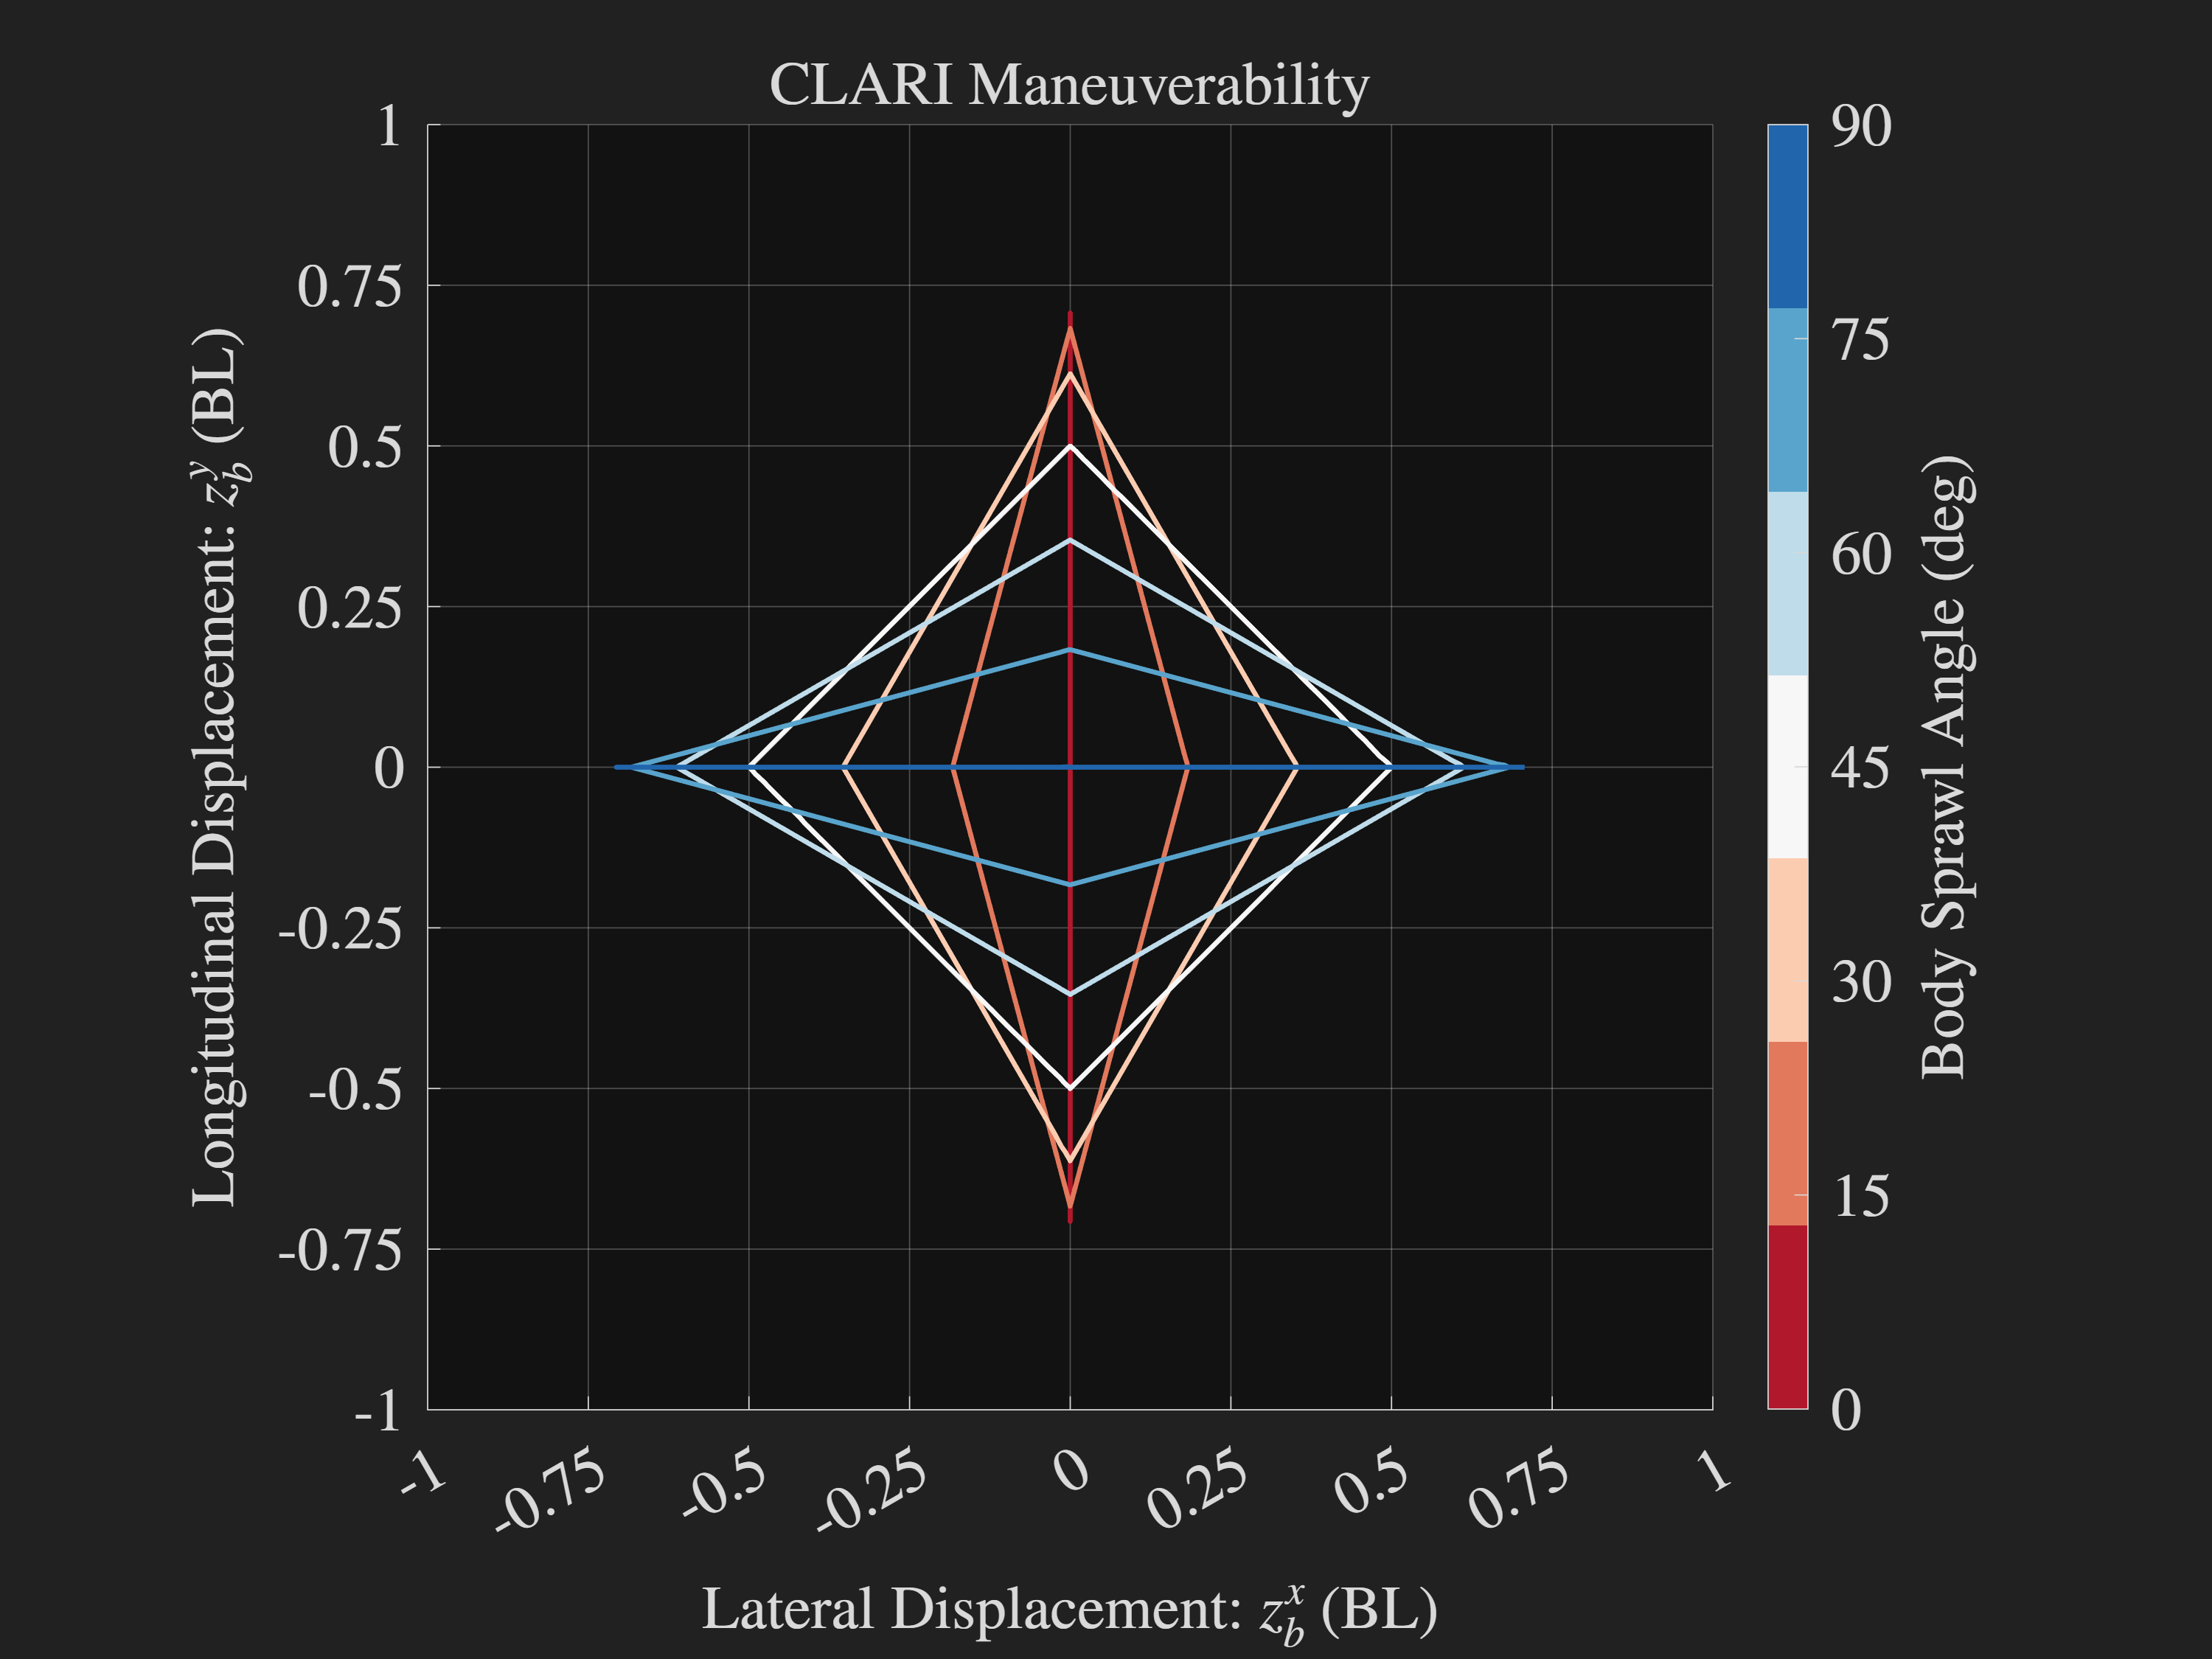

% package the base parameters for simulation
params = [];
params.dnum = dnum;
params.na = na; params.nl = nl;
params.sHat = swingHat;

% sweep the body sprawl angles
sNum = 7; % CHOOSE a small number of angles to sweep the set over
nalpha_b = linspace(bodySprawlParam(1), bodySprawlParam(2), sNum);

% sweep the maneuverability phases to get the full set
% ... 1 is again 0 as the phase connects on itself
gNum = dnum; mPhase = linspace(0, 1, gNum+1); mPhase = mPhase(1:end-1);

% define the colormap and fontsize for plotting
fS = 25;
cMapSprawl = [178,24,43;
              214,96,77;
              244,165,130;
              253,219,199;
              247,247,247;
              209,229,240;
              146,197,222;
              67,147,195;
              33,102,172]/255; % colormap for the differen body sprawl angles
cMapSprawl = interpColorAndCondition(...
                            (1:size(cMapSprawl, 1))', ...
                            cMapSprawl, ...
                            linspace(1, size(cMapSprawl, 1), sNum)' ...
                                         );

% simulate for each body condition
zb = cell(1, sNum); zbN = zb;
for j = 1:sNum
    params.nalpha_b = nalpha_b(j); % update the params struct with current sprawl
    zb{j} = nan(gNum, 3); % init array for current sprawl case
    for i = 1:gNum % iterate over each gait param and construct current set
        [~, ~, zb{j}(i, :)] = simulateSineSwingGaits(fA, params, mPhase(i));
    end
    zbN{j} = zb{j}; zbN{j}(:, 1:2) = zbN{j}(:, 1:2)/bodyLength;
end

% plot the maneuverability map for the nominal body sprawl
f = figure('units', 'pixels', 'position', [0 0 1200 900]); set(f,'Visible','on');
ax = gca; hold(ax, "on"); 
grid(ax, "on");
for j = 1:sNum
    plot(ax, ...
        [zbN{j}(:, 1); zbN{j}(1, 1)], ... % x-disp
        [zbN{j}(:, 2); zbN{j}(1, 2)], ... % y-disp
        '-', 'LineWidth', lW_s, 'Color', [cMapSprawl(j, :)]); % , 0.75
end
axis(ax, "equal"); ax.FontSize = 25;
xlim(ax, [-1, 1]); ylim(ax, [-1, 1]);
xticks(ax, -1:0.25:1); yticks(ax, -1:0.25:1);
colormap(ax, cMapSprawl); clim(ax, rad2deg(bodySprawlParam(1:2)));
cb = colorbar(ax, "eastoutside", "Ticks", ...
    rad2deg(linspace(bodySprawlParam(1), bodySprawlParam(2), sNum)),...
             "FontSize", fS, "TickLabelInterpreter", "latex");
cb.Label.String = 'Body Sprawl Angle (deg)'; cb.Label.Interpreter = "latex";
xlabel(ax, 'Lateral Displacement: $z_b^x$ (BL)', FontSize=fS);
ylabel(ax, 'Longitudinal Displacement: $z_b^y$ (BL)', FontSize=fS);
title(ax, 'CLARI Maneuverability', FontSize=fS);